# To find calculate the density

## load the file and ask the user for E and K range

close all;
clear
selpath =uigetdir(' ');     %% to select the folder you want to work in
files = dir(fullfile(selpath,'*.txt'));     %% to store all the file names with .txt extension
filepath = fullfile({files.folder}, {files.name});     %% to generate filepaths for all the txt files in the folder

EK_Userbounds = inputdlg({'Enter the CB E upper bound (eV)','Enter the CB E lower bound (eV)','Enter the Xton E upper bound (eV)','Enter the Xton E lower bound (eV)','Enter the VB E upper bound (eV)','Enter the VB E lower bound (eV)','Enter the K upper bound (Angs-1)','Enter the K lower bound (Angs-1)','Enter the Q upper bound (Angs-1)','Enter the Q lower bound (Angs-1)'},...
              'Input the E and K range', [1 50; 1 50; 1 50; 1 50; 1 50; 1 50; 1 50; 1 50; 1 50; 1 50], {'2.75','2.25','2.25','1.75','0.5','-1', '1.0', '1.5', '0.4', '0.9'}); %% asking the user to enter the E and K bounds
EK_Userbounds = cellfun(@str2num,EK_Userbounds); %% to convert the cell values to array of number for easier access down the line



## read one of the the data file in the folder

file_num = 2;
data = readmatrix(filepath{file_num}); %% to read the data file. Using readmatrix as we know the format of our file is floating and we want to use matrix form for ease of use later.
Energy_Scale = data(2:size(data,1),1); %% scale generated from MM's code
K_scale = data(1,2:size(data,2)); %% scale generated from MM's code
data1 = data(2:size(data,1),2:size(data,2)); %% full data without the scales

## creating the working data for CB, Xton and VB in the specified range

E_UB_CB = find(abs(Energy_Scale- EK_Userbounds(1)) < 0.005);%% find the column number for the energy upper bound
E_LB_CB = find(abs(Energy_Scale- EK_Userbounds(2)) < 0.005);%% find the column number for the energy lower bound
E_UB_X = find(abs(Energy_Scale- EK_Userbounds(3)) < 0.005); 
E_LB_X = find(abs(Energy_Scale- EK_Userbounds(4)) < 0.005);
E_UB_VB = find(abs(Energy_Scale- EK_Userbounds(5)) < 0.005); 
E_LB_VB = find(abs(Energy_Scale- EK_Userbounds(6)) < 0.004);
K_UB = find(abs(K_scale- EK_Userbounds(7)) < 0.005); % K range chosen by the user
K_LB = find(abs(K_scale- EK_Userbounds(8)) < 0.005);
K_LB_1 = find(abs(K_scale+ EK_Userbounds(7)) < 0.005);% K range opposite to the one used by user
K_UB_1 = find(abs(K_scale+ EK_Userbounds(8)) < 0.005);

Q_UB = find(abs(K_scale- EK_Userbounds(9)) < 0.005); % K range chosen by the user
Q_LB = find(abs(K_scale- EK_Userbounds(10)) < 0.005);
Q_LB_1 = find(abs(K_scale+ EK_Userbounds(9)) < 0.005);% K range opposite to the one used by user
Q_UB_1 = find(abs(K_scale+ EK_Userbounds(10)) < 0.005);


if (EK_Userbounds(7)<0) && (EK_Userbounds(8)<0) %% to make sure the ranges are in correct order
    working_Kscale = K_scale(K_LB:K_UB); %% k scale for both VB and Xton
    working_data_CB = data1(E_UB_CB(1):E_LB_CB(1),K_LB:K_UB); %% working data for CB
    working_Escale_CB = Energy_Scale(E_UB_CB(1):E_LB_CB(1)); %% working Escale for  CB
    working_data_X = data1(E_UB_X(1):E_LB_X(1),K_LB:K_UB); %% working data for Xton 
    working_Escale_X = Energy_Scale(E_UB_X(1):E_LB_X(1)); %% working Escale for Xton 
    working_data_VB = data1(E_UB_VB(1):E_LB_VB,K_LB:K_UB); %% working data for VB
    working_Escale_VB = Energy_Scale(E_UB_VB(1):E_LB_VB(1)); %% working data for VB

    working_data_CBX = data1(E_UB_CB(1):E_LB_X(1),K_LB:K_UB); %% working data for CB
    working_Escale_CBX = Energy_Scale(E_UB_CB(1):E_LB_X(1)); %% working Escale for  CB
    
    working_Kscale_1 = K_scale(K_LB_1:K_UB_1); %% k scale for both VB and Xton
    working_data_CB_1 = data1(E_UB_CB(1):E_LB_CB(1),K_LB_1:K_UB_1); %% working data for CB
    working_Escale_CB_1 = Energy_Scale(E_UB_CB(1):E_LB_CB(1)); %% working Escale for  CB
    working_data_X_1 = data1(E_UB_X(1):E_LB_X(1),K_LB_1:K_UB_1); %% working data for Xton 
    working_Escale_X_1 = Energy_Scale(E_UB_X(1):E_LB_X(1)); %% working Escale for Xton 
    working_data_VB_1 = data1(E_UB_VB(1):E_LB_VB(1),K_LB_1:K_UB_1); %% working data for VB
    working_Escale_VB_1 = Energy_Scale(E_UB_VB(1):E_LB_VB(1)); %% working data for VB

    working_data_CBX_1 = data1(E_UB_CB(1):E_LB_X(1),K_LB_1:K_UB_1); %% working data for CB
    working_Escale_CBX_1 = Energy_Scale(E_UB_CB(1):E_LB_X(1)); %% working Escale for  CB    
    
    working_Qscale = K_scale(Q_LB:Q_UB); %% k scale for both VB and Xton
    working_data_QCB = data1(E_UB_CB(1):E_LB_CB(1),Q_LB:Q_UB); %% working data for CB
    working_Escale_QCB = Energy_Scale(E_UB_CB(1):E_LB_CB(1)); %% working Escale for  CB
    working_data_QX = data1(E_UB_X(1):E_LB_X(1),Q_LB:Q_UB); %% working data for Xton 
    working_Escale_QX = Energy_Scale(E_UB_X(1):E_LB_X(1)); %% working Escale for Xton 
    
    working_data_QCBX = data1(E_UB_CB(1):E_LB_X(1),Q_LB:Q_UB); %% working data for CB
    working_Escale_QCBX = Energy_Scale(E_UB_CB(1):E_LB_X(1)); %% working Escale for  CB
    
    working_Qscale_1 = K_scale(Q_LB_1:Q_UB_1); %% k scale for both VB and Xton
    working_data_QCB_1 = data1(E_UB_CB(1):E_LB_CB(1),Q_LB_1:Q_UB_1); %% working data for CB
    working_Escale_QCB_1 = Energy_Scale(E_UB_CB(1):E_LB_CB(1)); %% working Escale for  CB
    working_data_QX_1 = data1(E_UB_X(1):E_LB_X(1),Q_LB_1:Q_UB_1); %% working data for Xton 
    working_Escale_QX_1 = Energy_Scale(E_UB_X(1):E_LB_X(1)); %% working Escale for Xton 
    
    working_data_QCBX_1 = data1(E_UB_CB(1):E_LB_X(1),Q_LB_1:Q_UB_1); %% working data for CB
    working_Escale_QCBX_1 = Energy_Scale(E_UB_CB(1):E_LB_X(1)); %% working Escale for  CB
    
  
    
elseif (EK_Userbounds(7)>0) && (EK_Userbounds(8)>0)
    working_Kscale = K_scale(K_UB:K_LB); %% k scale for both VB and Xton
    working_data_CB = data1(E_UB_CB(1):E_LB_CB(1),K_UB:K_LB); %% working data for CB
    working_Escale_CB = Energy_Scale(E_UB_CB(1):E_LB_CB(1)); %% working Escale for  CB
    working_data_X = data1(E_UB_X(1):E_LB_X(1),K_UB:K_LB); %% working data for Xton 
    working_Escale_X = Energy_Scale(E_UB_X(1):E_LB_X(1)); %% working Escale for Xton 
    working_data_VB = data1(E_UB_VB(1):E_LB_VB(1),K_UB:K_LB); %% working data for VB
    working_Escale_VB = Energy_Scale(E_UB_VB(1):E_LB_VB(1)); %% working data for VB

    working_data_CBX = data1(E_UB_CB(1):E_LB_X(1),K_UB:K_LB); %% working data for CB
    working_Escale_CBX = Energy_Scale(E_UB_CB(1):E_LB_X(1)); %% working Escale for  CB
    
    working_Kscale_1 = K_scale(K_UB_1:K_LB_1); %% k scale for both VB and Xton
    working_data_CB_1 = data1(E_UB_CB(1):E_LB_CB(1),K_UB_1:K_LB_1); %% working data for CB
    working_Escale_CB_1 = Energy_Scale(E_UB_CB(1):E_LB_CB(1)); %% working Escale for  CB
    working_data_X_1 = data1(E_UB_X(1):E_LB_X(1),K_UB_1:K_LB_1); %% working data for Xton 
    working_Escale_X_1 = Energy_Scale(E_UB_X(1):E_LB_X(1)); %% working Escale for Xton 
    working_data_VB_1 = data1(E_UB_VB(1):E_LB_VB(1),K_UB_1:K_LB_1); %% working data for VB
    working_Escale_VB_1 = Energy_Scale(E_UB_VB(1):E_LB_VB(1)); %% working data for VB

    working_data_CBX_1 = data1(E_UB_CB(1):E_LB_X(1),K_UB_1:K_LB_1); %% working data for CB
    working_Escale_CBX_1 = Energy_Scale(E_UB_CB(1):E_LB_X(1)); %% working Escale for  CB    
    
    working_Qscale = K_scale(Q_UB:Q_LB); %% k scale for both VB and Xton
    working_data_QCB = data1(E_UB_CB(1):E_LB_CB(1),Q_UB:Q_LB); %% working data for CB
    working_Escale_QCB = Energy_Scale(E_UB_CB(1):E_LB_CB(1)); %% working Escale for  CB
    working_data_QX = data1(E_UB_X(1):E_LB_X(1),Q_UB:Q_LB); %% working data for Xton 
    working_Escale_QX = Energy_Scale(E_UB_X(1):E_LB_X(1)); %% working Escale for Xton 
    
    working_data_QCBX = data1(E_UB_CB(1):E_LB_X(1),Q_UB:Q_LB); %% working data for CB
    working_Escale_QCBX = Energy_Scale(E_UB_CB(1):E_LB_X(1)); %% working Escale for  CB
    
    working_Qscale_1 = K_scale(Q_UB_1:Q_LB_1); %% k scale for both VB and Xton
    working_data_QCB_1 = data1(E_UB_CB(1):E_LB_CB(1),Q_UB_1:Q_LB_1); %% working data for CB
    working_Escale_QCB_1 = Energy_Scale(E_UB_CB(1):E_LB_CB(1)); %% working Escale for  CB
    working_data_QX_1 = data1(E_UB_X(1):E_LB_X(1),Q_UB_1:Q_LB_1); %% working data for Xton 
    working_Escale_QX_1 = Energy_Scale(E_UB_X(1):E_LB_X(1)); %% working Escale for Xton 
    
    working_data_QCBX_1 = data1(E_UB_CB(1):E_LB_X(1),Q_UB_1:Q_LB_1); %% working data for CB
    working_Escale_QCBX_1 = Energy_Scale(E_UB_CB(1):E_LB_X(1)); %% working Escale for  CB
end

## plot the working data for both K's and Q's

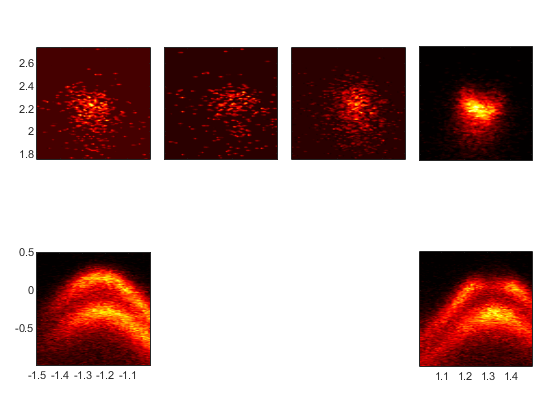

t = tiledlayout(2,4); %create a tiled layout for the plots. 
% Here the position is specified to resize the plots to ones liking. The arguments are as follows [x spacing, y spacing, x size, ysize].
% zero postion is the left bottom corner.

ax1 = nexttile; %the first tile/subplot
[D,h] = contourf(working_Kscale_1, working_Escale_CBX_1, working_data_CBX_1, 50); %% here h can be used to set the parameters of the contour after plotting
colormap("hot");
set(h,'LineColor','none'); %% to not have contour lines in the plots
daspect(ax1,[1 2 1]); %to disable the auto strectch -to-fill aspect of matlab.
% [1 2 3] indicates that the length from 0 to 1 along the x-axis is equal to the length from 0 to 2 along the y-axis and 0 to 3 along the z-axis. For equal data unit lengths in all directions, use [1 1 1].

ax2 = nexttile; %the second tile/subplot
[C,h] = contourf(working_Qscale_1, working_Escale_QCBX_1, working_data_QCBX_1, 50); %% here h can be used to set the parameters of the contour after plotting
colormap("hot");
set(h,'LineColor','none'); %% to not have contour lines in the plots
daspect(ax2,[1 2 1]); %to disable the auto strectch -to-fill aspect of matlab.
% [1 2 3] indicates that the length from 0 to 1 along the x-axis is equal to the length from 0 to 2 along the y-axis and 0 to 3 along the z-axis. For equal data unit lengths in all directions, use [1 1 1].

ax3 = nexttile; %the third tile/subplot
[B,h] = contourf(working_Qscale, working_Escale_QCBX, working_data_QCBX, 50); %% here h can be used to set the parameters of the contour after plotting
colormap("hot");
set(h,'LineColor','none'); %% to not have contour lines in the plots
daspect(ax3,[1 2 1]); %to disable the auto strectch -to-fill aspect of matlab.
% [1 2 3] indicates that the length from 0 to 1 along the x-axis is equal to the length from 0 to 2 along the y-axis and 0 to 3 along the z-axis. For equal data unit lengths in all directions, use [1 1 1].

ax4 = nexttile; %the fourth tile/subplot
[A,h] = contourf(working_Kscale, working_Escale_CBX, working_data_CBX, 50); %% here h can be used to set the parameters of the contour after plotting
colormap("hot");
set(h,'LineColor','none'); %% to not have contour lines in the plots
daspect(ax4,[1 2 1]); %to disable the auto strectch -to-fill aspect of matlab.
% [1 2 3] indicates that the length from 0 to 1 along the x-axis is equal to the length from 0 to 2 along the y-axis and 0 to 3 along the z-axis. For equal data unit lengths in all directions, use [1 1 1].

ax5 = nexttile;%the fifth tile/subplot
[E,h] = contourf(working_Kscale_1, working_Escale_VB_1, working_data_VB_1, 50); %% here h can be used to set the parameters of the contour after plotting
colormap("hot");
set(h,'LineColor','none');
daspect(ax5,[1 3 1]); %to disable the auto strectch -to-fill aspect of matlab
% [1 2 3] indicates that the length from 0 to 1 along the x-axis is equal to the length from 0 to 2 along the y-axis and 0 to 3 along the z-axis. For equal data unit lengths in all directions, use [1 1 1].


ax6 = nexttile(8);%the sixth tile/subplot
[F,h] = contourf(working_Kscale, working_Escale_VB, working_data_VB, 50); %% here h can be used to set the parameters of the contour after plotting
colormap("hot");
set(h,'LineColor','none');
daspect(ax6,[1 3 1]); %to disable the auto strectch -to-fill aspect of matlab
% [1 2 3] indicates that the length from 0 to 1 along the x-axis is equal to the length from 0 to 2 along the y-axis and 0 to 3 along the z-axis. For equal data unit lengths in all directions, use [1 1 1].


linkaxes([ax1,ax5],'x'); % to link the 'x' axis for both the plots
linkaxes([ax4,ax6],'x'); % to link the 'x' axis for both the plots
xticklabels([ax1,ax2,ax3,ax4],{});

linkaxes([ax1,ax2,ax3,ax4],'y'); % to link the 'y' axis for both the plots
linkaxes([ax5,ax6],'y'); % to link the 'y' axis for both the plots
yticklabels([ax2,ax3,ax4,ax6],{});

t.Padding = 'compact'; % space around the perimeter of the layout
t.TileSpacing = 'compact'; % space betwen the tiles/subplots


%%%%%%---Alternate way to resize the plots---%%%%%%


% t = tiledlayout(2,1,'Position',[0.3 0.1 0.45 0.9]); %create a tiled layout for the plots. 
% % Here the position is specified to resize the plots to ones liking. The arguments are as follows [x spacing, y spacing, x size, ysize].
% % zero postion is the left bottom corner.
% 
% ax1 = nexttile; %the first tile/subplot
% [A,h] = contourf(working_Kscale, working_Escale_CBX, working_data_CBX, 50); %% here h can be used to set the parameters of the contour after plotting
% colormap("hot");
% set(h,'LineColor','none'); %% to not have contour lines in the plots
% 
% ax2 = nexttile;%the second tile/subplot
% [C,h] = contourf(working_Kscale, working_Escale_VB, working_data_VB, 50); %% here h can be used to set the parameters of the contour after plotting
% colormap("hot");
% set(h,'LineColor','none');
% 
% linkaxes([ax1,ax2],'x'); % to link the 'x' axis for both the plots
% xticklabels(ax1,{});
% t.Padding = 'loose'; % space around the perimeter of the layout
% t.TileSpacing = 'compact'; % space betwen the tiles/subplots
% t.PositionConstraint = 'outerposition'; %Some scenarios can trigger the Axes object to automatically resize. 
% % For example, interactively resizing the figure or adding a title or axis labels activates automatic resizing. 
% % Sometimes, the new axes size cannot satisfy both the Position and OuterPosition values, so the PositionConstraint property indicates which values to preserve. 
% % Specify the PositionConstraint property as one of these values:
% % 'outerposition' — Preserve the OuterPosition value. Use this option when you do not want the axes or any of the surrounding text to extend beyond a certain outer boundary. 
% % MATLAB adjusts the size of the inner area of the axes (where plots appear) to try to fit the contents within the outer boundary.
% % 'innerposition' — Preserve the InnerPosition value. Use this option when you want the inner area of the axes to remain a certain size within the figure. This option sometimes causes text to run off the figure.

%%%%%%------%%%%%%


## summing the line cuts for CB + Xton, and VB

% % a = movsum(working_data_VB, 3);
% % b = movsum(working_data_CBX, 3);
% %%if we wanted to get density now, all we have to do is s = sum(working_data_VB,'all') and so on.

## Double gaussian function

% double_gauss = @(f,working_Escale_VB) f(1)+ f(2)*exp(-(working_Escale_VB-f(3)).^2/(2*f(4)^2)) + f(5)*exp(-(working_Escale_VB-f(6)).^2/(2*f(7)^2)); %% define the double gaussian function
% 
% dg_parameter_names = {'k', 'y0', 'e_y0', 'A1', 'e_A1', 'xc1', 'e_xc1', 'sig1', 'e_sig1', 'A2', 'e_A2', 'xc2', 'e_xc2', 'sig2', 'e_sig2'}; %% creating the heading of the parameter names and their errors for saving in a text file

## VB double gaussian fitting

% for i = 1:size(working_Kscale,2)
%     [pks,locs,wdths] = findpeaks(smooth(flip(working_data_VB(:,i)),5),flip(working_Escale_VB),'MinPeakWidth',0.04,'MinPeakHeight',5,'MinPeakDistance',0.25); %finding the intial guess for fitting
%     if size(pks,1) == 2 %% to prevent errors if the program catches more than 2 peaks
%         dg_Ig_VB = [0,pks(2),locs(2),wdths(2)/2.355,pks(1),locs(1),wdths(1)/2.355];
%         dg_lb_VB = [0, pks(2)-15, locs(2)-0.2, 0.02, pks(1)-5, locs(1)-0.2, 0.03]; %% lower bound
%         dg_ub_VB = [0, pks(2)+15, locs(2)+0.2, 0.2, pks(1)+5, locs(1)+0.2, 0.4]; %% upper bound
%     else
%         dg_Ig_VB = [0,5, -0.1, 0.05, 5, -0.7, 0.05];
%         dg_lb_VB = [0, 1, -0.6, 0.03, 1, -1, 0.03]; %% lower bound
%         dg_ub_VB = [0, 1E6, 0.2, 0.2, 1E6, -0.3, 1]; %% upper bound
%     end
%     [fit, resnorm, residual, exitflag, output, lambda, jacobian]= lsqcurvefit(double_gauss,dg_Ig_VB,working_Escale_VB,working_data_VB(:,i),dg_lb_VB,dg_ub_VB); %% doing least square fitting
%     ci = transpose(nlparci(fit,residual,'jacobian',jacobian)); %% to get the upper and lower bounds of the error in parameters. Here for the lsqcurvefit, we are using 95% confidence interval, which is satisfied but the variance in parameters. 95% condidence interval means 2*std. So to get std of parameters, we do the following: (check next line)
%     parameter_error = (ci(2,:)-fit)/2; %% to get 1*std from the 95% confidence interval bounds on the parameters whcih is 2*std
%     T = table(working_Kscale(1,i), fit(1,1), parameter_error(1,1), fit(1,2), parameter_error(1,2), fit(1,3), parameter_error(1,3), fit(1,4), parameter_error(1,4), fit(1,5), parameter_error(1,5), fit(1,6), parameter_error(1,6), fit(1,7), parameter_error(1,7), 'VariableNames', dg_parameter_names);
%     writetable(T, fullfile(files(file_num).folder,'parameters',strcat('VB_fitting_parameters_',files(file_num).name)), "Delimiter",'tab',"WriteMode","append"); %% to write the output of the parameters after fitting
%     plot(working_Escale_VB, working_data_VB(:,i), 'b-', working_Escale_VB,double_gauss(fit,working_Escale_VB),'r-'); %% plotting the data and the fits
%     yl = ylim; xl = xlim; grid on; legend(mat2str(working_Kscale(1,i),4),'double gaussian fit'); title('VB fitting'); xlabel('Energy (ev)'); ylabel('Counts (A.U)');ax = gca; %% ax is to specify the axis type. gca means current axis
%     str = {compose('VB2 A = %.3f \n VB2 xc = %.3f eV \n VB2 σ = %.3f eV' ,fit(5:end)), compose('y0 = %.3f \n VB1 A = %.3f \n VB1 xc = %.3f eV \n VB1 σ = %.3f eV' ,fit(1:4))};
%     text([xl(1)+0.1 xl(1)+1.25],[yl(2)-((yl(1)+yl(2))/2) yl(2)-((yl(1)+yl(2))/2)],str); %% to automatically set the position of the fit parameters
%     exportgraphics(ax, strcat('k=',mat2str(working_Kscale(1,i),4),' VB fitting.png')); %% to export the plots for later check
% end

% % % % [pks,locs] = findpeaks(flip(working_data_VB(:,1)),flip(working_Escale_VB),'MinPeakWidth',0.3)
% % % % plot(flip(working_data_VB(:,1)),flip(working_Escale_VB));
% % % for j= 1:size(working_data_VB,2)
% % %     [pks,loc,] = findpeaks(flip(smooth(working_data_VB(:,j),5)),flip(working_Escale_VB),'MinPeakWidth',0.05,'MinPeakHeight',2,'WidthReference','halfheight');ax = gca;
% % % %     exportgraphics(ax, strcat('k=',mat2str(working_Kscale(1,j),4),' Peak finding.png'));
% % % end

% % % [pks,loc,w] = findpeaks(flip(smooth(working_data_VB(:,45)),5), flip(working_Escale_VB),'MinPeakWidth',0.05,'MinPeakHeight',2);
% % % findpeaks(flip(smooth(working_data_VB(:,45)),5), flip(working_Escale_VB),'MinPeakWidth',0.05,'MinPeakHeight',2)
% % 
% % 

% % new_file_name = split(files(file_num).name,'_');
% % new_file_name = split(new_file_name(5),'-');
% % name = strcat(cellstr(new_file_name(1)), '_VB_fitting_parameters_',files(file_num).name)
% % EK_Userbounds(7)

% num = 40;
% [pks,locs,w] = findpeaks(smooth(flip(working_data_VB(:,num)),5),flip(working_Escale_VB),'MinPeakWidth',0.04,'MinPeakHeight',5,'MinPeakDistance',0.25);
% findpeaks(smooth(flip(working_data_VB(:,num)),5),flip(working_Escale_VB),'MinPeakWidth',0.04,'MinPeakHeight',5,'MinPeakDistance',0.25, 'Annotate',"extents");
% plot(working_Escale_VB,working_data_VB(:,num), flip(working_Escale_VB), smooth(flip(working_data_VB(:,num))));
% locs
% 
% 
% 
% 